digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
'nndatasets','DigitDataset');

imds = imageDatastore(digitDatasetPath, ...
'IncludeSubfolders',true,'LabelSource','foldernames');

numTrainFiles = 750;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

tr_in = readall(imdsTrain);
tr_tg = imdsTrain.Labels;

ts_in = readall(imdsValidation);
ts_tg = imdsValidation.Labels;

omega_b = 0.2;
Nh = 784;
ts = 5;
f = @(bias, hidden_weights, hidden) tanh(bias + hidden_weights*hidden);
x0 = zeros(Nh,1);
phi = @eulerForward;
eps = 0.1;
eigs = -1:-1:-Nh; rho = 0.9;
dns = 0.1; a = 0.5;
%a = 0.1;
ws = 0;
lambda_r = 0.1;
%Nl = 1;
seed = 1;

addpath src

net = NeuralODE(omega_b, Nh, ts, f, phi, eps, eigs, dns, ws, lambda_r, seed);

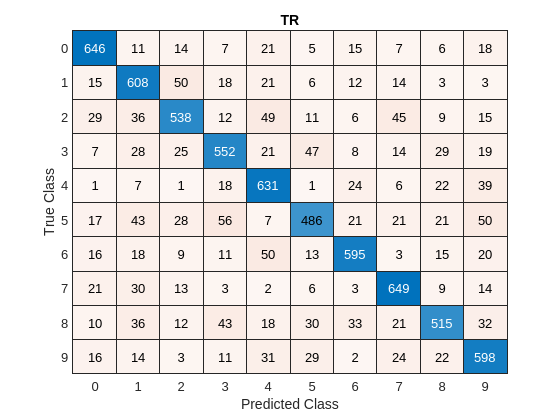

[net,pred_tr]=net.fit(tr_in,tr_tg);
figure
confusionchart(tr_tg, pred_tr);
title("TR")